## **Abdullah Ahmed**

**aa09303**

**Task 1 a)**

K = 4;
bb = ones(1, K) / K;
aa = 1;

ww = -pi:(pi/100):pi; 
H = freqz(bb, aa, ww);

subplot(2,1,1);
plot(ww, abs(H));
grid on;
xlabel('Normalized Radian Frequency (\omega)');
ylabel('|H(e^{j\omega})|');
title('Magnitude Response');

% Plot the phase response
subplot(2,1,2);
plot(ww, angle(H));
grid on;
xlabel('Normalized Radian Frequency (\omega)');
ylabel('Phase (radians)');
title('Phase Response');

**Task 1 b)**

The four-point averaging filter acts as a low pass, reducing high-frequency components while preserving low-frequency ones. This results in a smoothing, as rapid variations and noise are attenuated while gradual changes remain, making the signal more continuous.

**Task 1 c)**

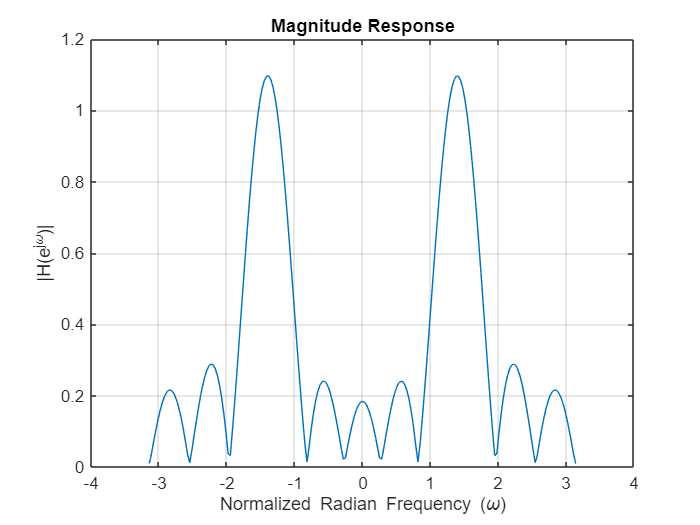

clc;
clear;
close all;

L = 10;
wc = 0.44 * pi;
n = 0:L-1;
bb = (2/L) * cos(wc * n); % Filter Coefficients

ww = linspace(-pi, pi, 201); % Frequency vector
H = freqz(bb, 1, ww);        % Frequency response

figure;
plot(ww, abs(H));
grid on;
xlabel('Normalized Radian Frequency (\omega)');
ylabel('|H(e^{j\omega})|');
title('Magnitude Response');

**Task 1 d)**

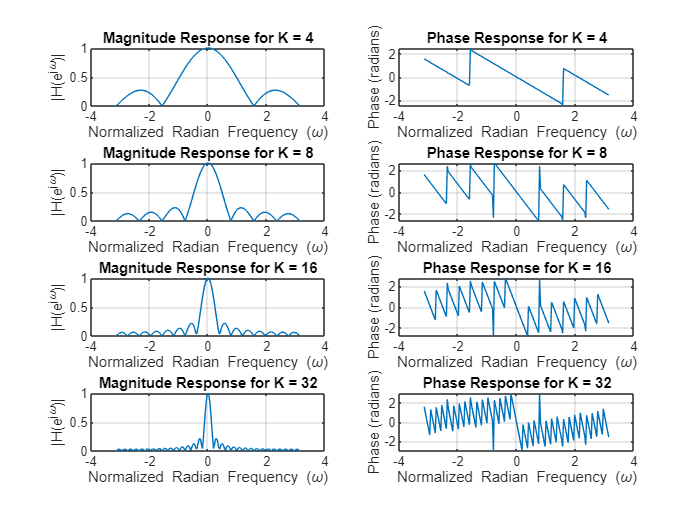

K_values = [4, 8, 16, 32];  % Different filter lengths
ww = -pi:(pi/100):pi;       % Frequency range

figure;
for i = 1:length(K_values)
    K = K_values(i);
    b = ones(1, K) / K;  % Averaging filter coefficients
    H = freqz(b, 1, ww); % Frequency response

    subplot(length(K_values), 2, 2*i - 1);
    plot(ww, abs(H)); grid on;
    title(['Magnitude Response for K = ', num2str(K)]);
    xlabel('Normalized Radian Frequency (\omega)');
    ylabel('|H(e^{j\omega})|');

    subplot(length(K_values), 2, 2*i);
    plot(ww, angle(H)); grid on;
    title(['Phase Response for K = ', num2str(K)]);
    xlabel('Normalized Radian Frequency (\omega)');
    ylabel('Phase (radians)');
end

As the value of K increases, the number of lobes in the magnitude graph increases, and the waves or peaks in the angle graph also become more frequent.

**Task 2 a)**

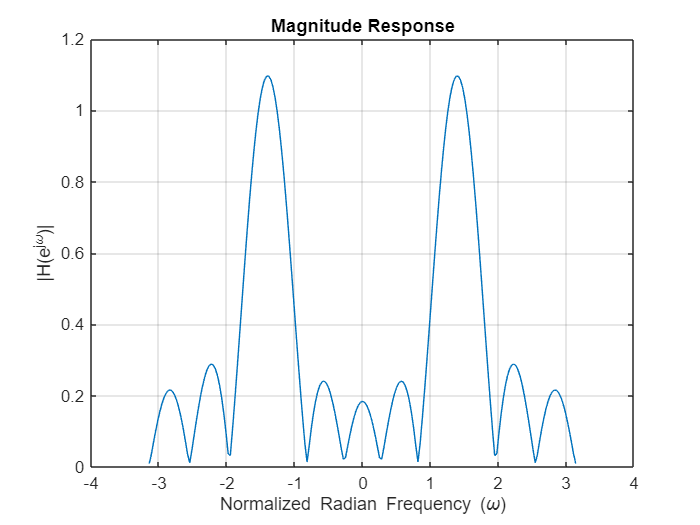

clc;
clear;
close all;

L = 10; 
wc = 0.44 * pi;            
ww = -pi:(pi/100):pi;     

figure;
n = 0:L-1;
h = (2/L) * cos(wc * n);
H = freqz(h, 1, ww);

plot(ww, abs(H)); grid on;
title('Magnitude Response');
xlabel('Normalized Radian Frequency (\omega)');
ylabel('|H(e^{j\omega})|');

**Task 2 b)**

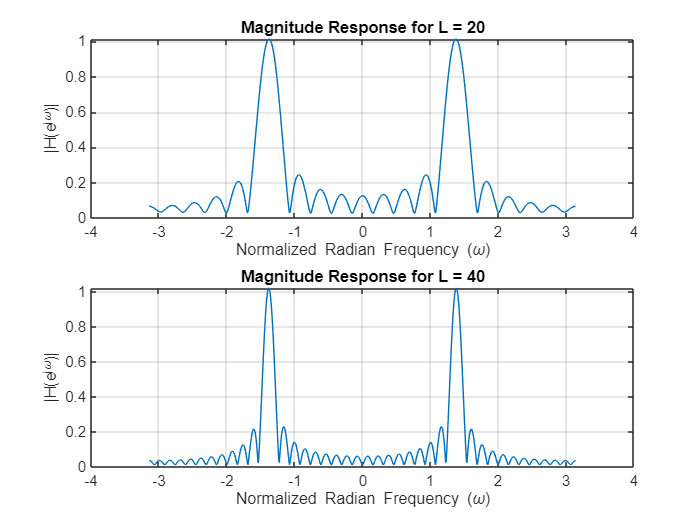

clc;
clear;
close all;

L_values = [20, 40]; 
ww = -pi:pi/400:pi; % Frequency vector

figure;
for i = 1:length(L_values)
    L = L_values(i);
    wc = 0.44 * pi;
    n = 0:L-1;
    h = (2/L) * cos(wc * n); % Filter Coefficients
    H = freqz(h, 1, ww);      % Frequency response

    subplot(2, 1, i);
    plot(ww, abs(H));
    grid on;
    xlabel('Normalized Radian Frequency (\omega)');
    ylabel('|H(e^{j\omega})|');
    title(['Magnitude Response for L = ' num2str(L)]);
end

**Task 2 c)**

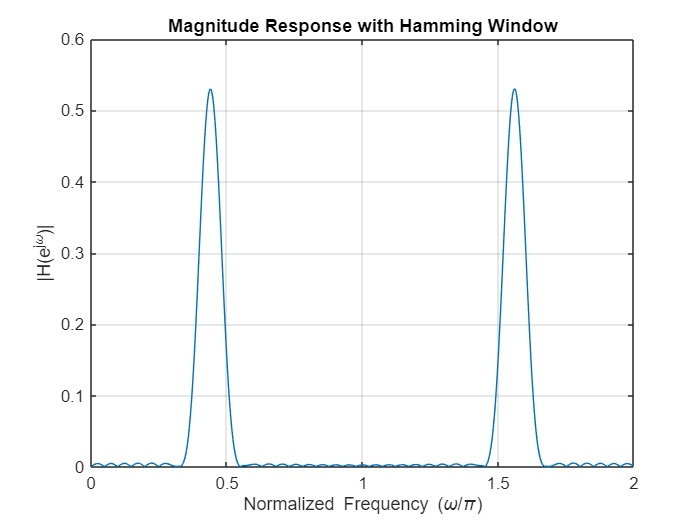

clc;
clear;
close all;

% Parameters
L = 40;                   % Filter length
wc = 0.44 * pi;           % Center frequency
n = 0:L-1;                % Sample indices

% Compute the FIR filter
h = (2/L) * cos(wc * n);

% Apply Hamming window
h = h .* hamming(L)';     % Element-wise multiplication with window

% Compute frequency response
[H, w] = freqz(h, 1, 1024, 'whole');

% Plot the magnitude response
figure;
plot(w/pi, abs(H));
grid on;
xlabel('Normalized Frequency (\omega/\pi)');
ylabel('|H(e^{j\omega})|');
title('Magnitude Response with Hamming Window');

**Task 2 d)**

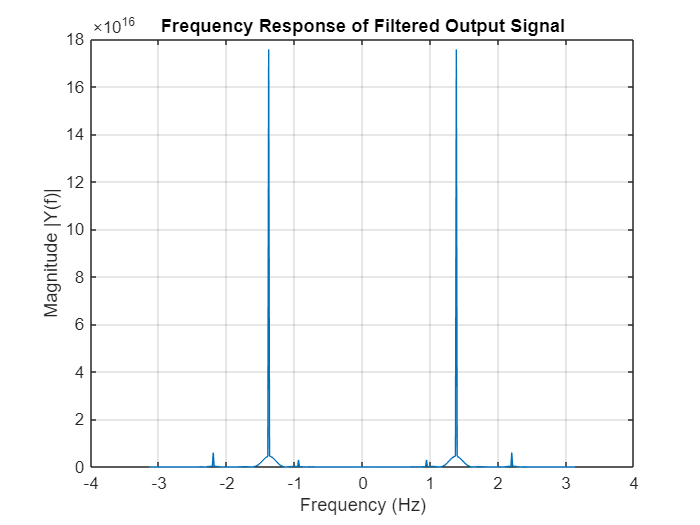

clc;
clear;
close all;

L = 50;                       
wc = 0.44 * pi;               
n = -(L-1)/2 : (L-1)/2;       

h = (2/L) * cos(wc * n);      
h = h / sum(h);               

fs = 2 * pi;                  
N = 500;                      
n = 0:N-1;                    
x = 10*cos(0.3*pi*n) + 40*cos(0.44*pi*n - pi/3) + 20*cos(0.7*pi*n - pi/4);

y = conv(x, h, 'same');

X = fft(y);  
Y = fftshift(X);
n_samples = length(Y);
fshift = (-n_samples/2:n_samples/2-1) * (fs/n_samples);

figure;
plot(fshift, abs(Y) / n_samples);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude |Y(f)|');
title('Frequency Response of Filtered Output Signal');